# disadNB-IoT simulation

## transmission

clear
%base message
dataLength=12*21*2;
messageBits= randi([0 1],dataLength,1)

messageBits =      0
     0
     1
     1
     0
     1
     1
     1
     1
     1


% messageBits=ones(dataLength,1)
%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      0
     3
     1
     3
     3
     3
     0
     0
     0
     1


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =    0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 + 0.7071i


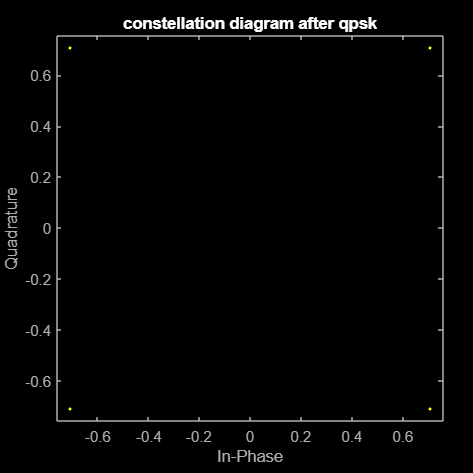

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

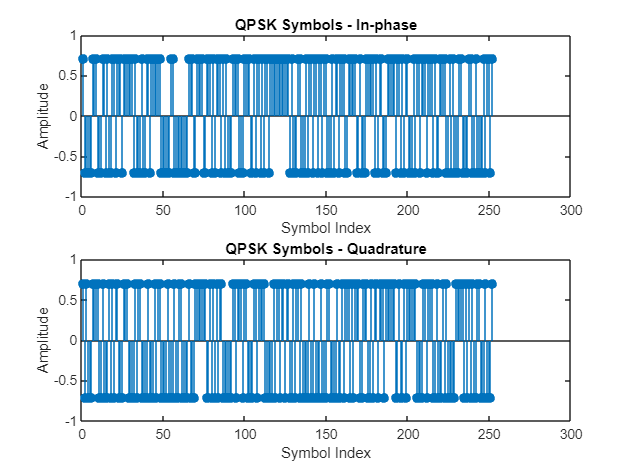


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


numSC=12;% # subcarriers
numSym=21;% # ofdm symbols
SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
t = (0:SPS-1) / samplingRate; %time vector
ofdmSignal = zeros(1, numSym * SPS);

cpLen=round(SPS/4);


ofdmMatrix = zeros(numSC,numSym);%12x7
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =    0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i
  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i
  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.70

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.1179 + 0.1179i   0.0000 + 0.3536i  -0.1179 - 0.2357i   0.0000 + 0.3536i  -0.2357 + 0.3536i  -0.1179 + 0.1179i   0.1179 - 0.2357i   0.2357 + 0.2357i   0.1179 + 0.1179i   0.1179 + 0.0000i   0.1179 - 0.2357i   0.0000 - 0.1179i  -0.1179 - 0.4714i   0.0000 + 0.2357i   0.0000 + 0.1179i  -0.2357 + 0.2357i  -0.1179 + 0.0000i   0.1179 - 0.3536i   0.2357 + 0.0000i   0.0000 + 0.0000i  -0.3536 - 0.2357i
   0.5419 - 0.1452i   0.1179 + 0.0000i   0.0431 - 0.2788i  -0.2630 - 0.0158i   0.0747 - 0.1610i  -0.0705 + 0.2630i   0.4398 + 0.2041i  -0.0747 + 0.1610i  -0.1610 + 0.1294i   0.0431 + 0.0431i  -0.0431 - 0.0431i   0.3378 + 0.0589i   0.1452 + 0.2199i  -0.3378 + 0.1768i  -0.3220 + 0.0316i  -0.1768 - 0.2199i   0.1768 - 0.2199i  -0.2199 + 0.0589i   0.1610 + 0.4830i  -0.3536 + 0.0863i   0.1610 - 0.1610i
  -0.3378 + 0.0589i   0.0431 + 0.0431i  -0.1610 - 0.0747i  -0.2199 + 0.2630i  -0.2788 + 0.0431i  -0.3809 + 0.3378i   0.1179 + 0.2041i   0.0000 + 0.4398i  -0.1179 + 0.1179i   0.1179 + 0.5577i   0.

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.1179 + 0.1179i   0.0000 + 0.3536i  -0.1179 - 0.2357i   0.0000 + 0.3536i  -0.2357 + 0.3536i  -0.1179 + 0.1179i   0.1179 - 0.2357i   0.2357 + 0.2357i   0.1179 + 0.1179i   0.1179 + 0.0000i   0.1179 - 0.2357i   0.0000 - 0.1179i  -0.1179 - 0.4714i   0.0000 + 0.2357i   0.0000 + 0.1179i  -0.2357 + 0.2357i  -0.1179 + 0.0000i   0.1179 - 0.3536i   0.2357 + 0.0000i   0.0000 + 0.0000i  -0.3536 - 0.2357i
   0.5419 - 0.1452i   0.1179 + 0.0000i   0.0431 - 0.2788i  -0.2630 - 0.0158i   0.0747 - 0.1610i  -0.0705 + 0.2630i   0.4398 + 0.2041i  -0.0747 + 0.1610i  -0.1610 + 0.1294i   0.0431 + 0.0431i  -0.0431 - 0.0431i   0.3378 + 0.0589i   0.1452 + 0.2199i  -0.3378 + 0.1768i  -0.3220 + 0.0316i  -0.1768 - 0.2199i   0.1768 - 0.2199i  -0.2199 + 0.0589i   0.1610 + 0.4830i  -0.3536 + 0.0863i   0.1610 - 0.1610i
  -0.3378 + 0.0589i   0.0431 + 0.0431i  -0.1610 - 0.0747i  -0.2199 + 0.2630i  -0.2788 + 0.0431i  -0.3809 + 0.3378i   0.1179 + 0.2041i   0.0000 + 0.4398i  -0.1179 + 0.1179i   0


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.1179 + 0.1179i
   0.5419 - 0.1452i
  -0.3378 + 0.0589i
  -0.2357 + 0.0000i
   0.0158 - 0.2630i
  -0.0705 + 0.2630i
   0.1179 - 0.1179i
   0.2199 + 0.1768i
   0.2199 + 0.1452i
   0.2357 + 0.2357i


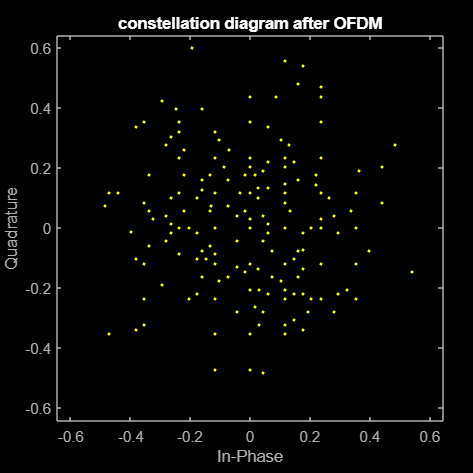

% plot ofdm signal

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

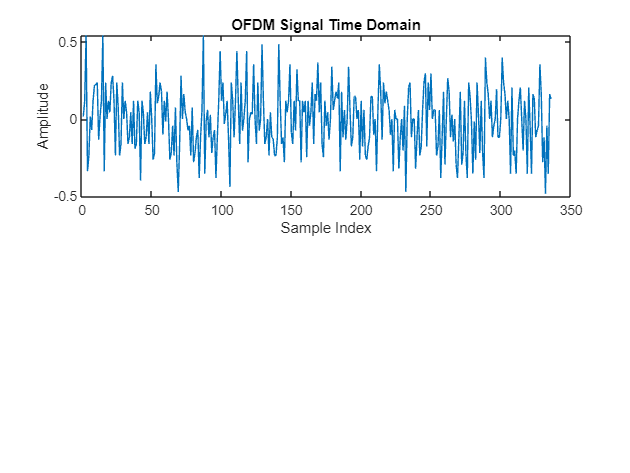


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

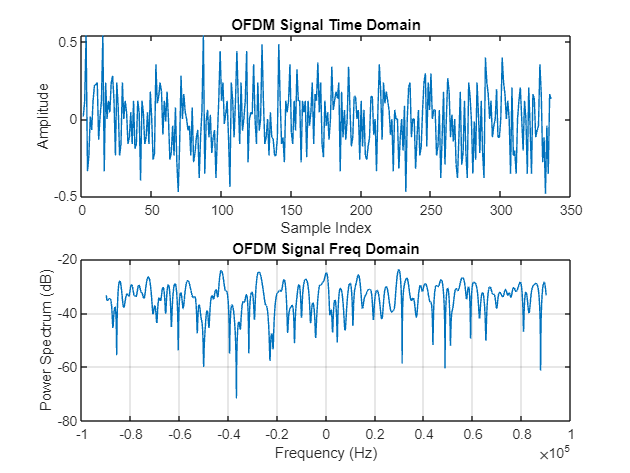


[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

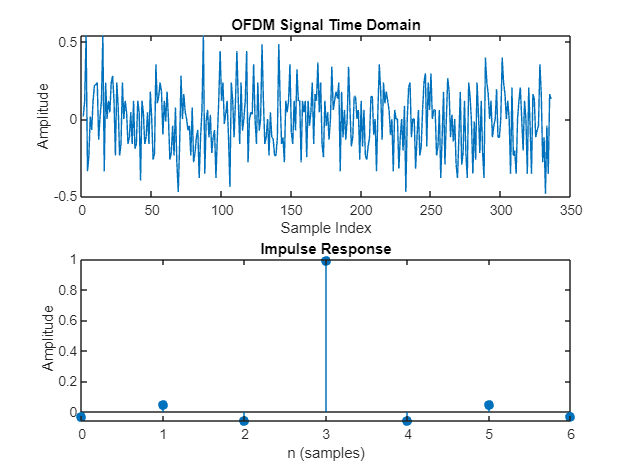

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

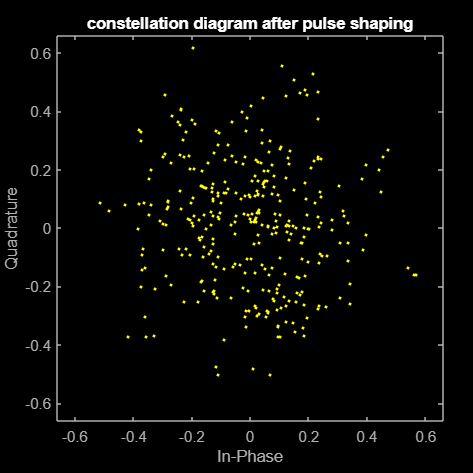


txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

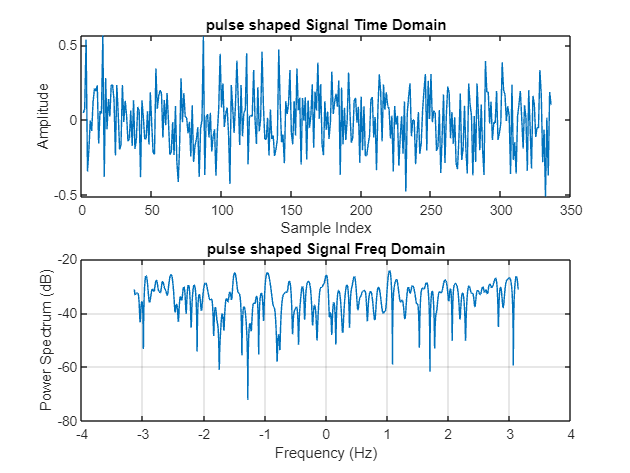


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

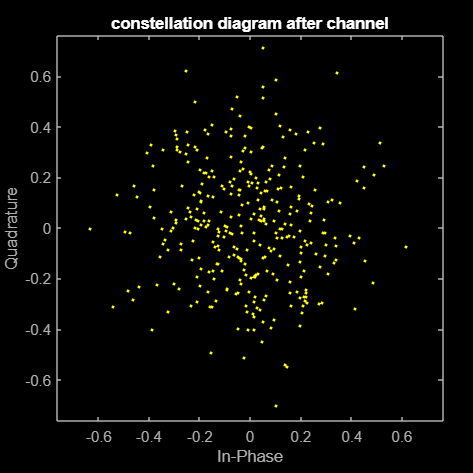

SNR=19;
rxSignal=awgn(txSignalShaped,SNR);
% rxSignal=txSignalShaped;

% Plot the time domain signal after channel
figure
scatterplot(rxSignal)
title('constellation diagram after channel');

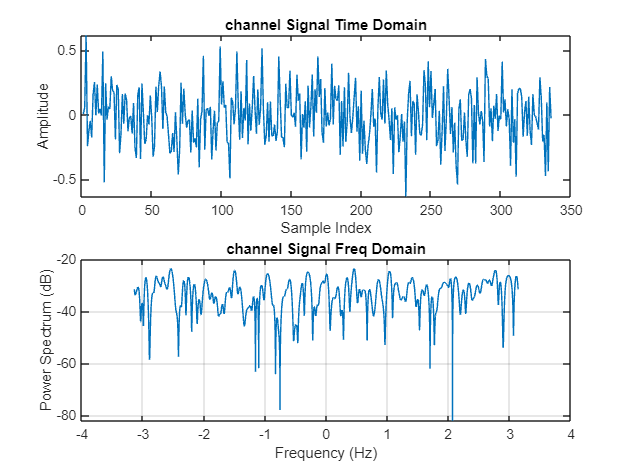


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(rxSignal));
title('channel Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(rxSignal);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('channel Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
matchedFilter = rcosdesign(rolloff, span, L);
rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
rxSignalFiltered

rxSignalFiltered =    0.0403 + 0.2049i
   0.0095 + 0.0247i
   0.6185 - 0.0550i
  -0.2659 + 0.0444i
  -0.0907 + 0.0243i
  -0.0647 - 0.4304i
  -0.1666 + 0.4304i
   0.1393 - 0.2052i
   0.2461 + 0.3705i
  -0.0236 + 0.0584i


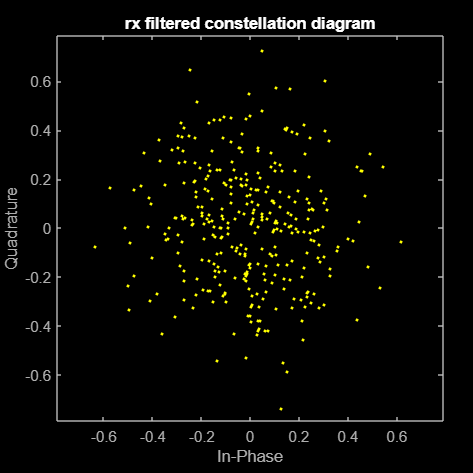


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);

figure;
scatterplot(rxSignalFiltered);
title('rx filtered constellation diagram');


%cp
rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.0403 + 0.2049i   0.2999 + 0.0076i  -0.1181 - 0.0990i   0.1517 - 0.5868i  -0.1084 - 0.2755i  -0.1200 + 0.0034i  -0.0130 + 0.1986i  -0.1959 + 0.0867i   0.4890 + 0.3038i  -0.2650 + 0.2733i  -0.3166 + 0.3188i  -0.0726 - 0.0760i  -0.1235 + 0.2408i  -0.1209 + 0.4440i  -0.0756 + 0.1977i  -0.0004 + 0.1374i  -0.3609 - 0.4320i  -0.1728 + 0.2148i   0.4454 + 0.0269i   0.0275 - 0.2676i  -0.1245 + 0.0007i
   0.0095 + 0.0247i  -0.1078 + 0.4559i  -0.0223 - 0.1065i  -0.0326 + 0.3868i  -0.2765 + 0.3717i  -0.2793 + 0.0529i  -0.1027 - 0.2673i   0.1927 + 0.3840i   0.0119 + 0.0384i   0.2366 + 0.0403i   0.2481 - 0.3048i  -0.0599 - 0.2022i  -0.0166 - 0.5278i   0.0037 + 0.0200i   0.0246 + 0.1557i  -0.1366 + 0.2407i  -0.1174 - 0.0405i   0.0044 - 0.3843i   0.2332 - 0.0993i  -0.0037 - 0.1512i  -0.2220 - 0.2734i
   0.6185 - 0.0550i   0.0993 - 0.0083i   0.0017 - 0.3585i  -0.2876 - 0.1541i   0.0372 - 0.3223i   0.1576 + 0.1269i   0.5420 + 0.2520i  -0.2222 + 0.1497i  -0.1881 + 0.0189i   0.0473 +

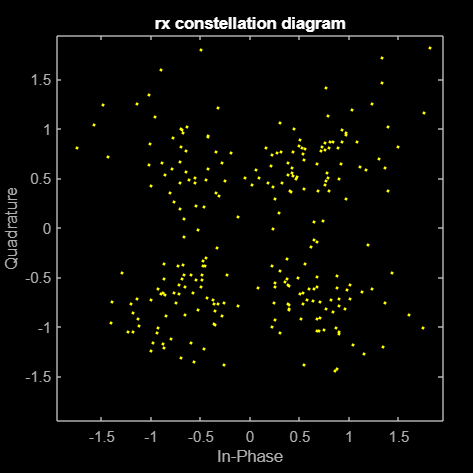

rxSymbols = rxSymbolsWithCP(cpLen+2:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);
figure;
scatterplot(rxQPSKSymbols);
title('rx constellation diagram');

% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 4

nbiot_ber=errors/dataLength

nbiot_ber = 0.0079


symbolRate=samplingRate/SPS

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

EbN0_sim=SNR*samplingRate/bitRate

EbN0_sim = 9.5000


SNR_linear = 10^(SNR / 10);
Eb_N0 = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 39.7164

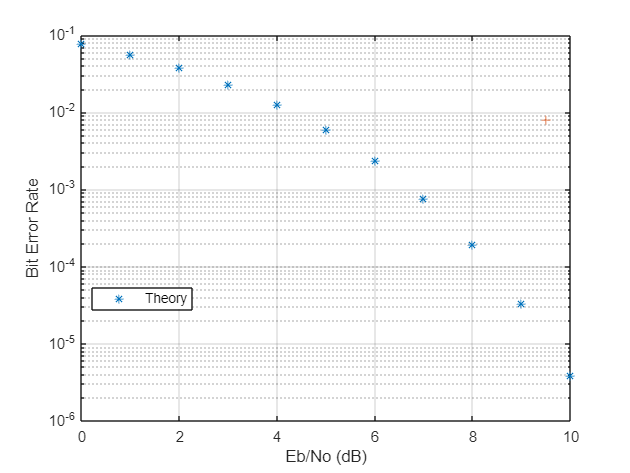

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')

legend('Theory','Location','Best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on